# ЛЧМ сигнал. Прохождение сигнала через согласованный фильтр.

fs=8e3;
dt=1/fs;
t=0:dt:1

t =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


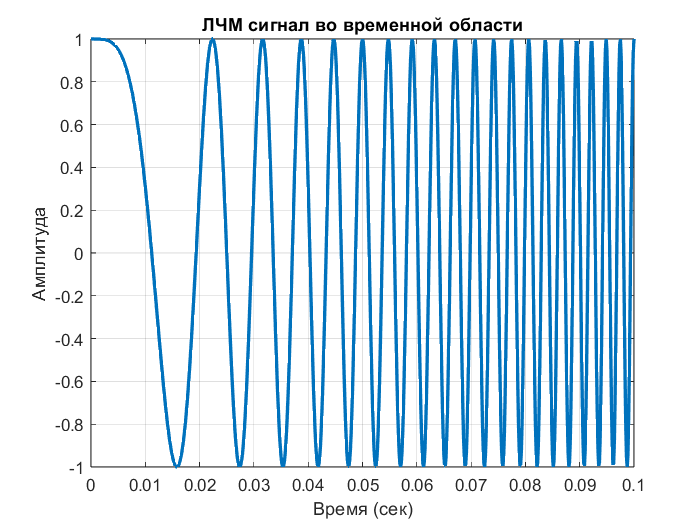

lchm_signal=chirp(t, 0, 1, 4000); %y=chirp(t, f0,t1, f1) функция для генерации лчм сигнала
plot(t, lchm_signal, 'LineWidth', 2); xlim([0 0.1]); grid on;
title('ЛЧМ сигнал во временной области');
xlabel('Время (сек)'); ylabel('Амплитуда');

ЛЧМ сигнал с наложенным АБГШ(Сигнал/Шум=10%)

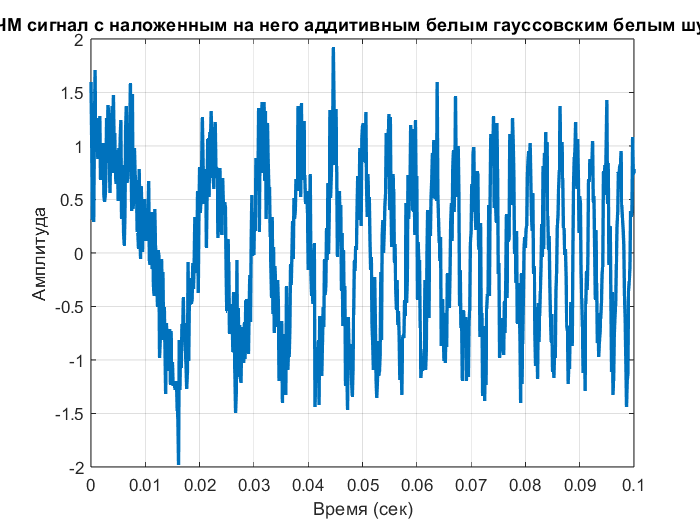

snr=10; % 
noisy_signal=awgn(lchm_signal, snr);
plot(t, noisy_signal, "LineWidth", 2); grid on; xlim([0 0.1]);
title('ЛЧМ сигнал с наложенным на него аддитивным белым гауссовским белым шумом');
xlabel('Время (сек)'); ylabel('Амплитуда');

Амплитудный спектр ЛЧМ сигнала

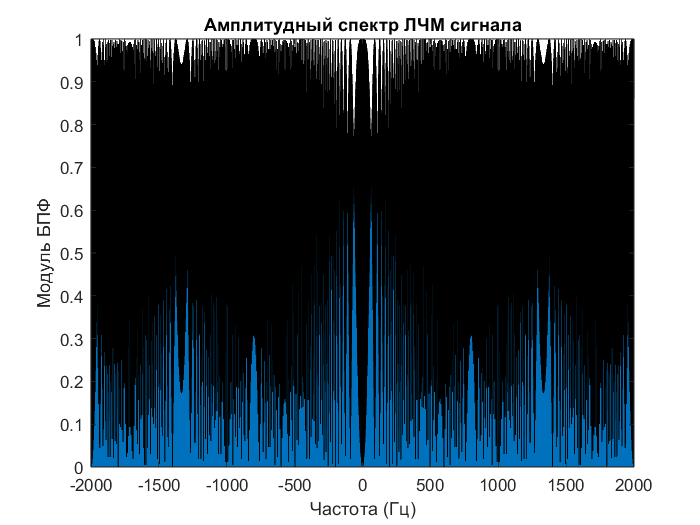

lchm_signal_fft=fftshift(lchm_signal);
F_lchm_signal=linspace(-fs/2, fs/2, length(lchm_signal));
area(F_lchm_signal, abs(lchm_signal));
xlim([-2e3 2e3]); grid on;
title('Амплитудный спектр ЛЧМ сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');

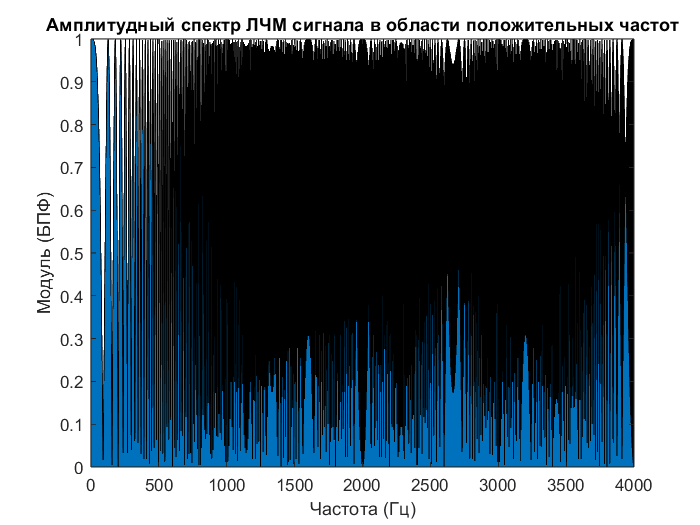

lchm_signal_positive=lchm_signal([1:length(lchm_signal)/2]);
F_lchm_signal_positive=linspace(0, fs/2, length(lchm_signal_positive));
area(F_lchm_signal_positive, abs(lchm_signal_positive));
title('Амплитудный спектр ЛЧМ сигнала в области положительных частот');
xlabel('Частота (Гц)');
ylabel('Модуль (БПФ)');

Фазовый спектр ЛЧМ сигнала

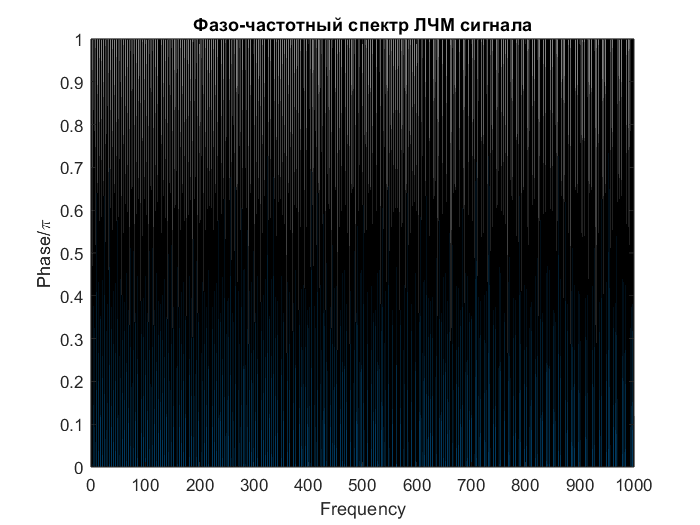

area(angle(lchm_signal_fft)/pi);
title("Фазо-частотный спектр ЛЧМ сигнала");
xlabel("Frequency");
ylabel("Phase/\pi");
xlim([0 1000]);

Амплитудный спектр ЛЧМ сигнала с наложенным АБГШ

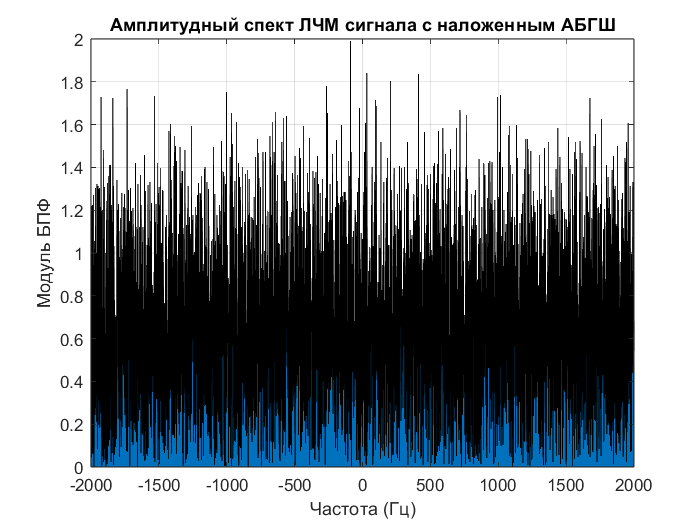

noisy_signal_fft=fftshift(noisy_signal);
F_noisy_signal=linspace(-fs/2, fs/2, length(noisy_signal));
area(F_noisy_signal, abs(noisy_signal));
xlim([-2e3 2e3]); grid on; title("Амплитудный спект ЛЧМ сигнала с наложенным АБГШ");
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');

Фазовый спектр ЛЧМ сигнала с наложенным АБГШ

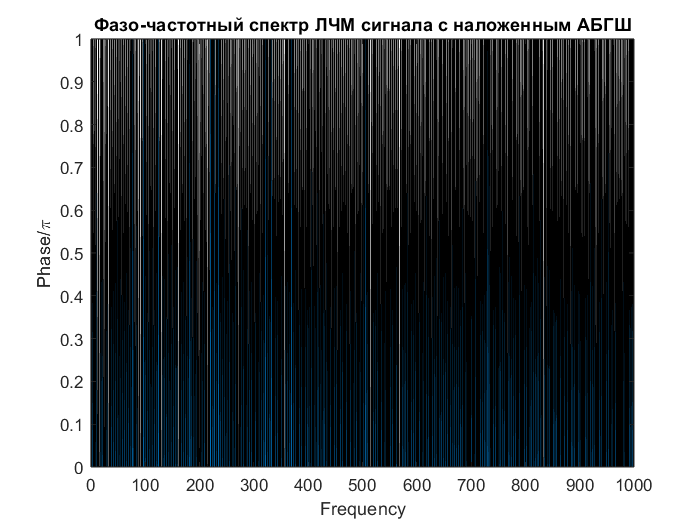

area(angle(noisy_signal_fft)/pi);
title("Фазо-частотный спектр ЛЧМ сигнала c наложенным АБГШ");
xlabel("Frequency");
ylabel("Phase/\pi");
xlim([0 1000]);

Спектральные плотности мощности

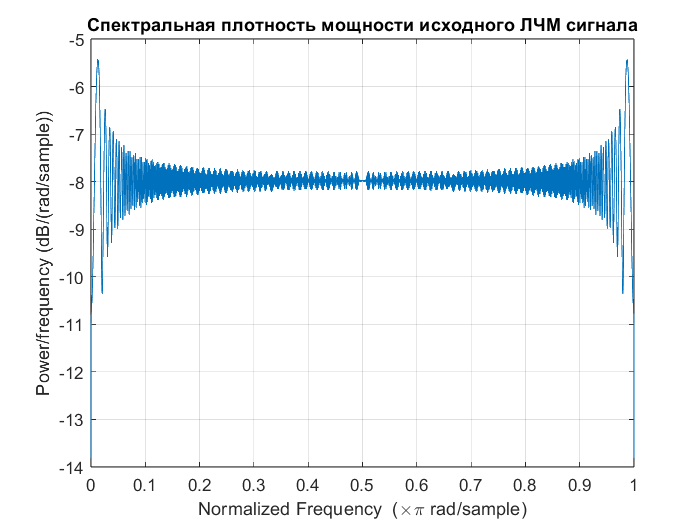

periodogram(lchm_signal);
grid on;
title("Спектральная плотность мощности исходного ЛЧМ сигнала");

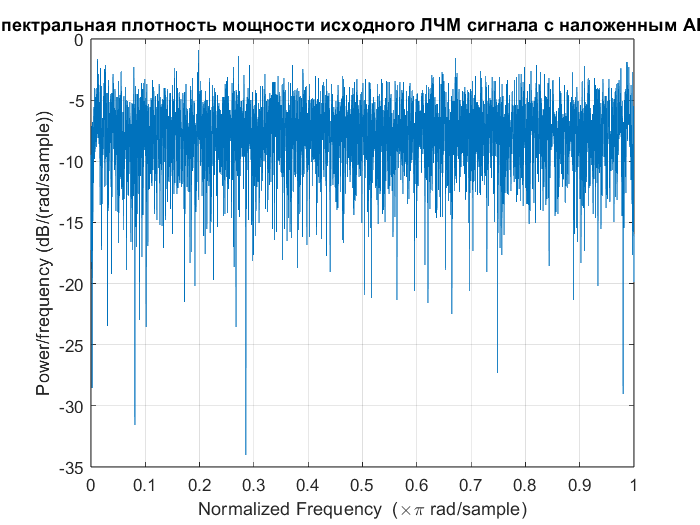


periodogram(noisy_signal);
grid on;
title("Спектральная плотность мощности исходного ЛЧМ сигнала c наложенным АБГШ");

Распределение отсчётов

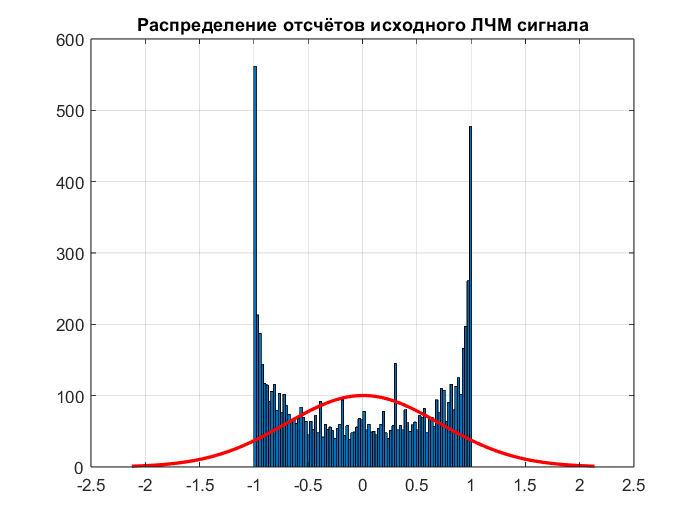

histfit(lchm_signal); grid on;
title("Распределение отсчётов исходного ЛЧМ сигнала");

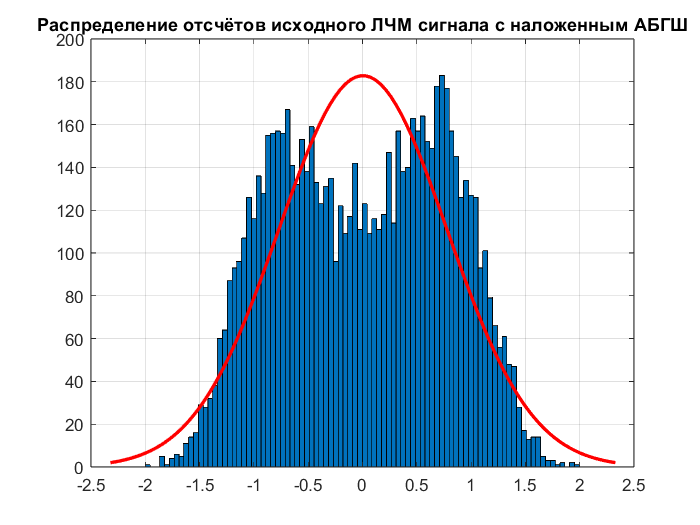


histfit(noisy_signal); grid on;
title("Распределение отсчётов исходного ЛЧМ сигнала c наложенным АБГШ");

Автокорреляционная функция 

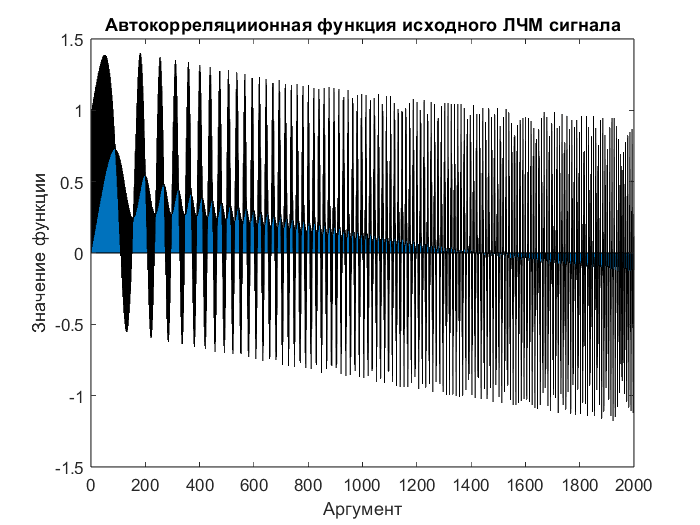

area(xcorr(detrend(lchm_signal))); xlim([0 2000]);
title("Автокорреляциионная функция исходного ЛЧМ сигнала");
xlabel("Аргумент"); ylabel("Значение функции"); 

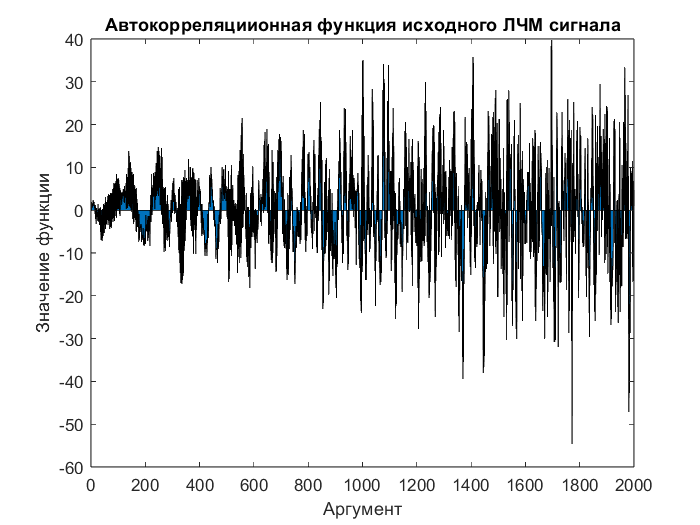


area(xcorr(detrend(noisy_signal))); xlim([0 2000]);
title("Автокорреляциионная функция исходного ЛЧМ сигнала");
xlabel("Аргумент"); ylabel("Значение функции"); 

Согласуем фильтр с заданным ЛЧМ сигналом без шума

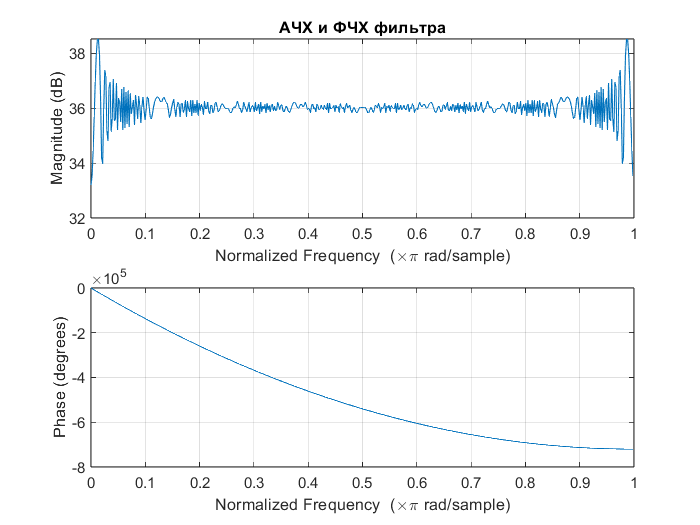

h_soglasovanni=fliplr(lchm_signal);
freqz(h_soglasovanni, 1);
title("АЧХ и ФЧХ фильтра");

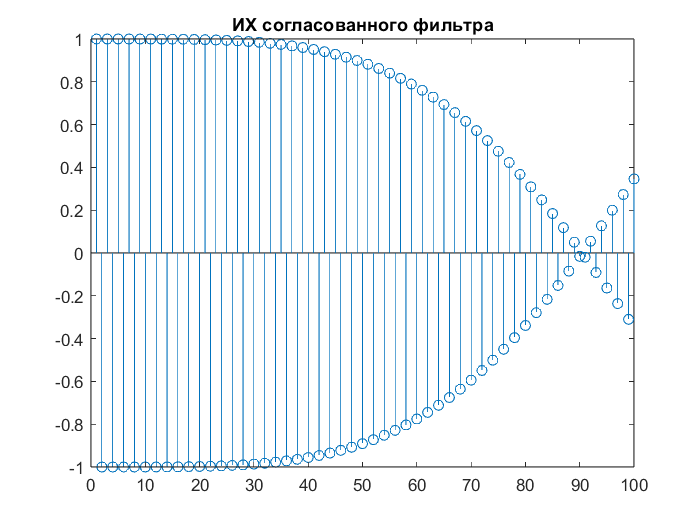

stem(h_soglasovanni); title("ИХ согласованного фильтра"); xlim([0 100])

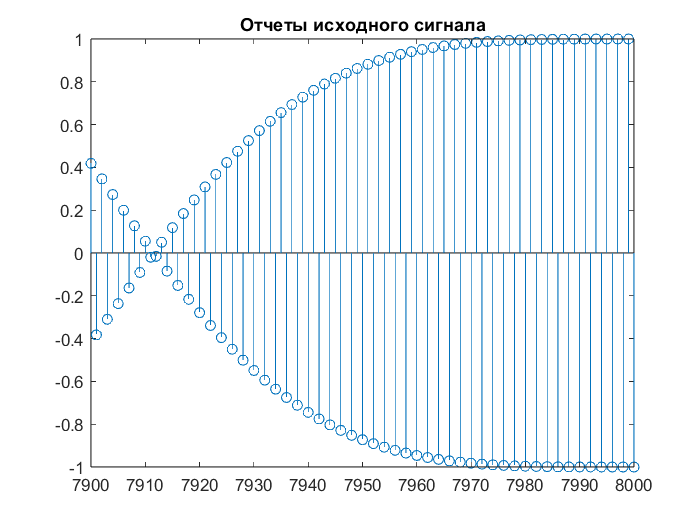

stem(lchm_signal); xlim([7900 8000]); title("Отчеты исходного сигнала")

Свертка сигнала с импульсной характеристикой согласованного фильтра

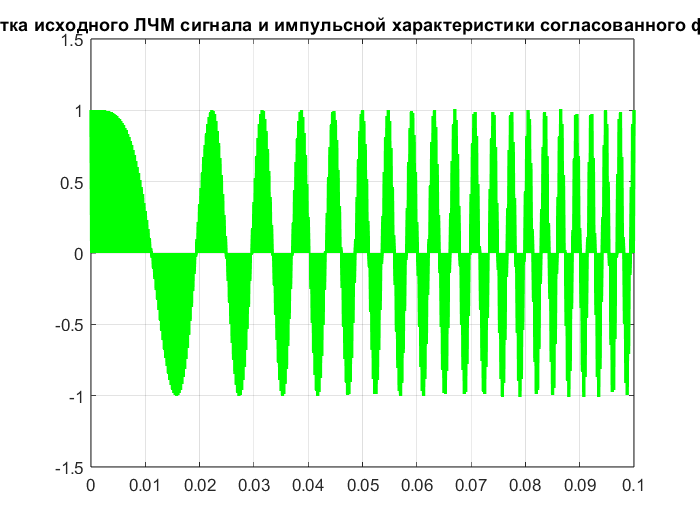

svertka_clear = conv(h_soglasovanni, lchm_signal);
svertka_noisy = conv(h_soglasovanni, noisy_signal);
plot(t, svertka_clear(1:length(t)), "LineWidth", 2, "Color", "green");
grid on; title("Свертка исходного ЛЧМ сигнала и импульсной характеристики согласованного фильтра"); xlim([0 0.1]);

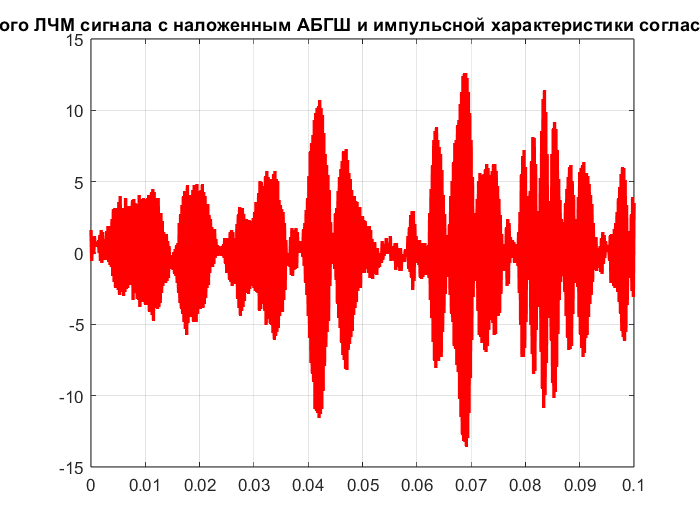

plot(t, svertka_noisy(1:length(t)), "LineWidth", 2, "Color", "red");
grid on; title("Свертка исходного ЛЧМ сигнала с наложенным АБГШ и импульсной характеристики согласованного фильтра"); xlim([0 0.1]);

Характеристики выходных сигналов

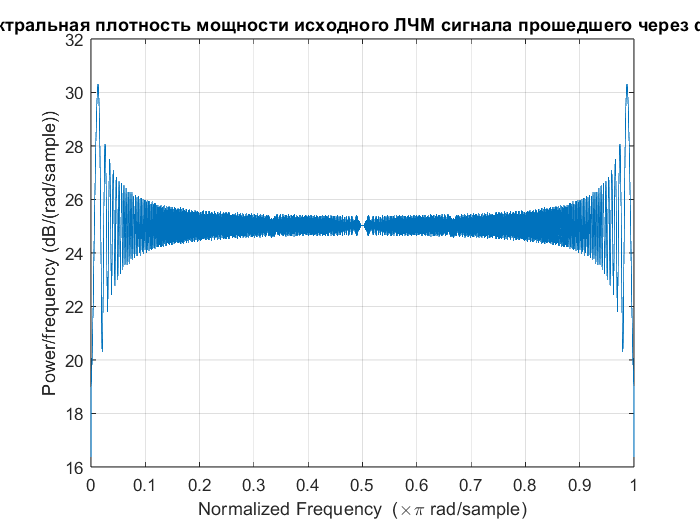

periodogram(svertka_clear);
grid on;
title("Спектральная плотность мощности исходного ЛЧМ сигнала прошедшего через фильтр");

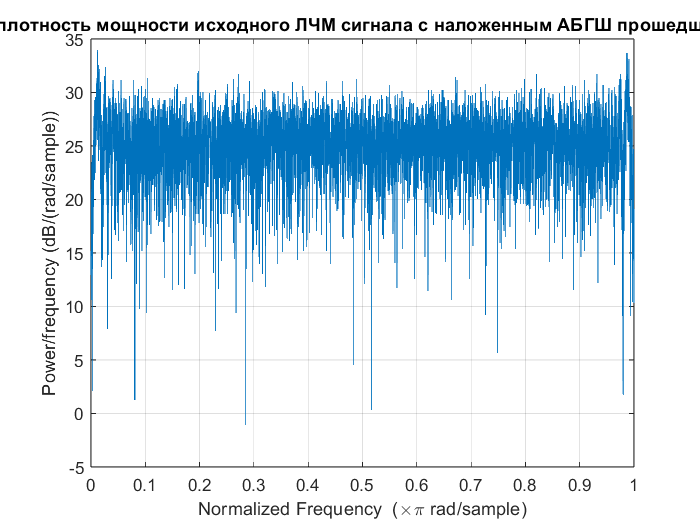

periodogram(svertka_noisy);
grid on;
title("Спектральная плотность мощности исходного ЛЧМ сигнала c наложенным АБГШ прошедшего через фильтр");

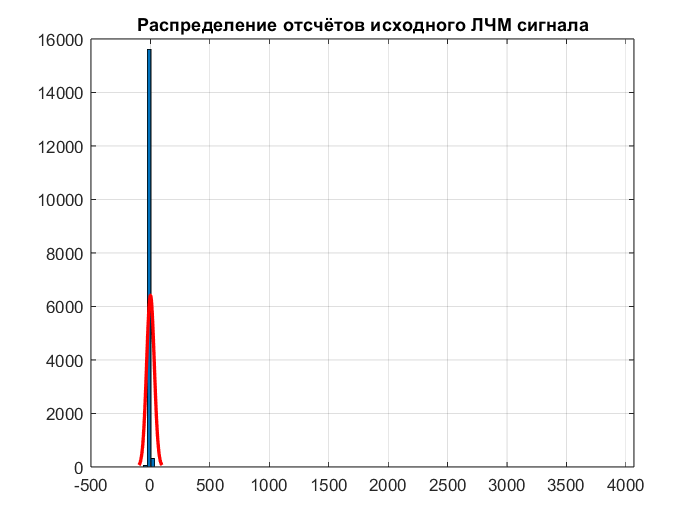

histfit(svertka_clear); grid on;
title("Распределение отсчётов исходного ЛЧМ сигнала");

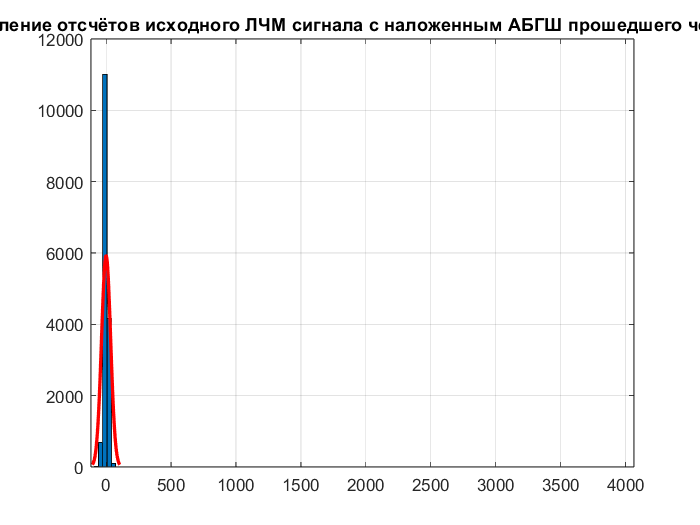

histfit(svertka_noisy); grid on;
title("Распределение отсчётов исходного ЛЧМ сигнала c наложенным АБГШ прошедшего через фильтр");

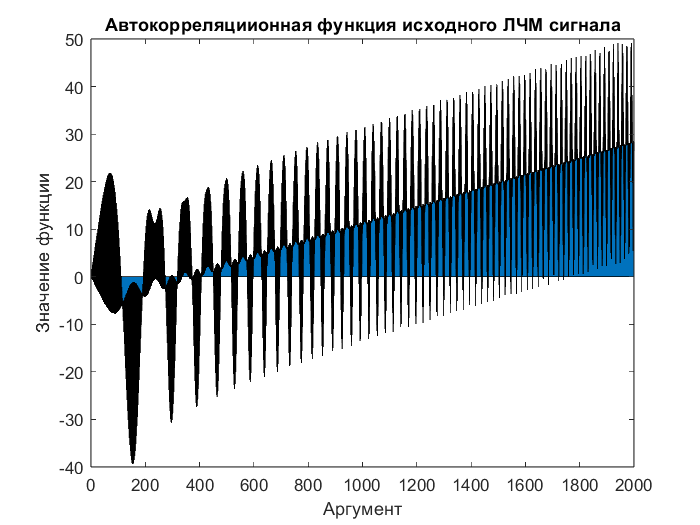

area(xcorr(detrend(svertka_clear))); xlim([0 2000]);
title("Автокорреляциионная функция исходного ЛЧМ сигнала");
xlabel("Аргумент"); ylabel("Значение функции"); 

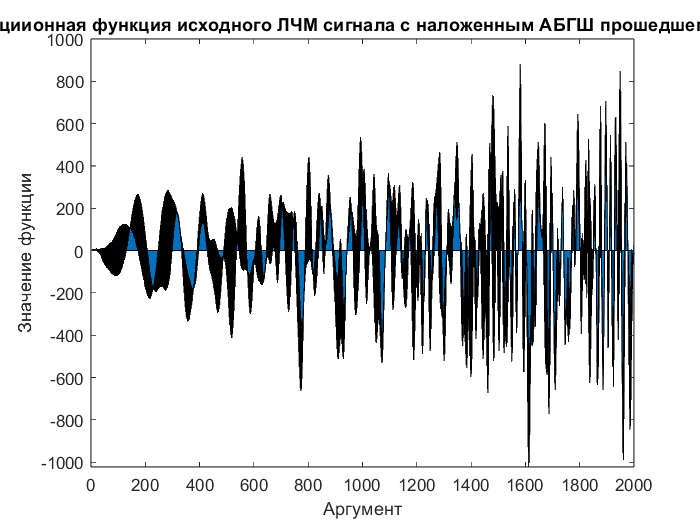

area(xcorr(detrend(svertka_noisy))); xlim([0 2000]);
title("Автокорреляциионная функция исходного ЛЧМ сигнала c наложенным АБГШ прошедшего через фильтр");
xlabel("Аргумент"); ylabel("Значение функции"); 

Амплитудные пектры выходных сигналов

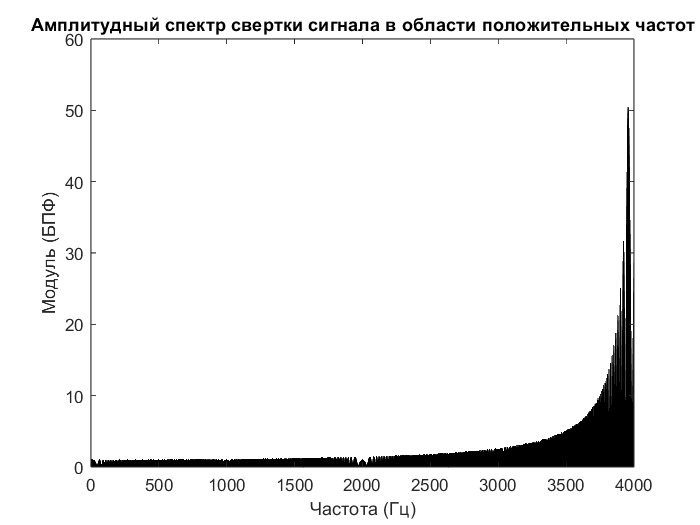

svertka_clear_positive=svertka_clear([1:length(svertka_clear)/2]);
F_svertka_clear_positive=linspace(0, fs/2, length(svertka_clear_positive));
area(F_svertka_clear_positive, abs(svertka_clear_positive));
title('Амплитудный спектр свертки сигнала в области положительных частот');
xlabel('Частота (Гц)'); ylabel('Модуль (БПФ)');

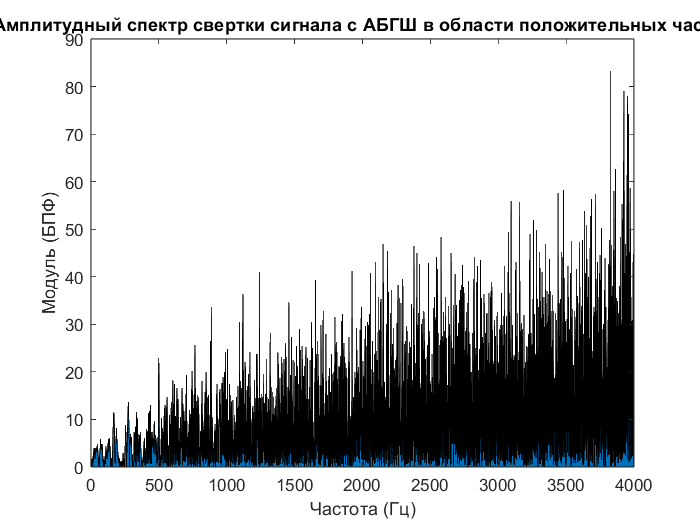

svertka_noisy_positive=svertka_noisy([1:length(svertka_noisy)/2]);
F_svertka_noisy_positive=linspace(0, fs/2, length(svertka_noisy_positive));
area(F_svertka_noisy_positive, abs(svertka_noisy_positive));
title('Амплитудный спектр свертки сигнала с АБГШ в области положительных частот');
xlabel('Частота (Гц)'); ylabel('Модуль (БПФ)');

Фазовые спектры выходных сигналов

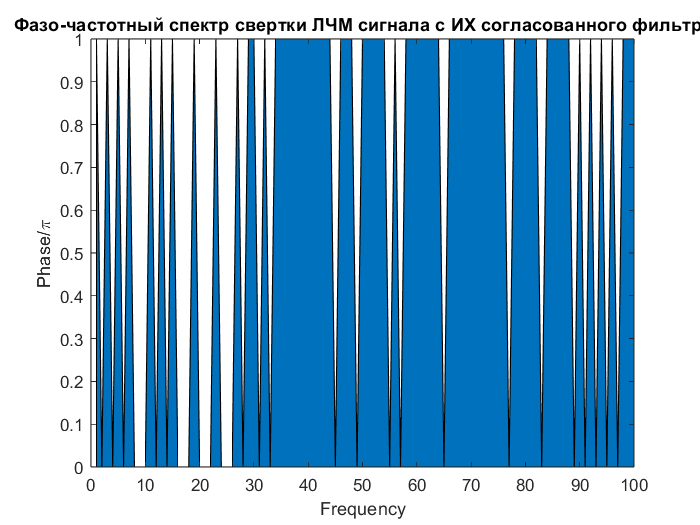

svertka_clear_fft = fftshift(svertka_clear);
area(angle(svertka_clear_fft)/pi);
title("Фазо-частотный спектр свертки ЛЧМ сигнала с ИХ согласованного фильтра");
xlabel("Frequency"); ylabel("Phase/\pi"); xlim([0 100]);

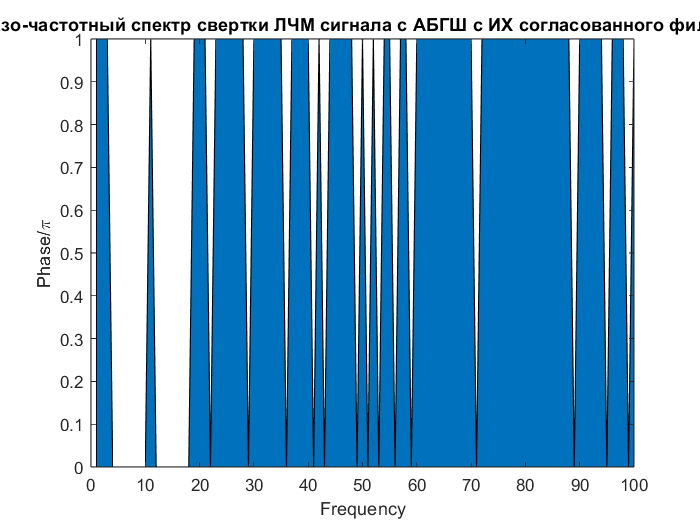

svertka_noisy_fft = fftshift(svertka_noisy);
area(angle(svertka_noisy_fft)/pi);
title("Фазо-частотный спектр свертки ЛЧМ сигнала с АБГШ с ИХ согласованного фильтра");
xlabel("Frequency"); ylabel("Phase/\pi"); xlim([0 100]);